# Bomb disposal robot

## Introduction

In this task, you'll decide a trajectory through the workspace of the robot and determine the corresponding joint angles to execute that trajectory. It is based on the MATLAB example

## Construct The Robot

Create a `rigidBodyTree` object and rigid bodies with their associated joints. Specify the geometric properties of each rigid body and add it to the robot.

% Start with a blank rigid body tree model.
robot = rigidBodyTree('DataFormat','column','MaxNumBodies',3);

% Add |'link1'| body with |'joint1'| joint.
body = rigidBody('link1');
joint = rigidBodyJoint('joint1', 'revolute');
setFixedTransform(joint,[0, pi/2, 0, 0],'dh');
body.Joint = joint;
addBody(robot, body, 'base');

% Add |'link2'| body with |'joint2'| joint.
body = rigidBody('link2');
joint = rigidBodyJoint('joint2','prismatic');
setFixedTransform(joint, [0, -pi/2, 1, 0],'dh');
body.Joint = joint;
addBody(robot, body, 'link1');

% Add |'link3'| body with |'joint3'| joint.
body = rigidBody('link3');
joint = rigidBodyJoint('joint3','revolute');
setFixedTransform(joint, [1, 0, 0, 0],'dh');
body.Joint = joint;
addBody(robot, body, 'link2');

## Display the robot

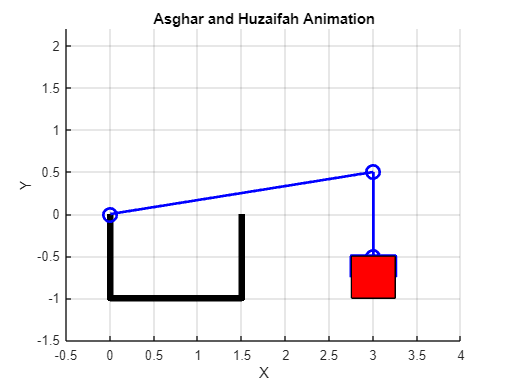

figure;
axis([-0.5 4 -1.5 2.2]);
grid on;
xlabel('X');
ylabel('Y');
title('Asghar and Huzaifah Animation')
% Draw the container
line([0 0 1.5 1.5],[0 -1 -1 0],[0 0 0 0],'Color','black','LineWidth',5);

% Configuration and End-effector location
q = [9.4623,3.0414,-99.4623];


% Draw the arm
P = [q(2)*cosd(q(1)), q(2)*sind(q(1))];
l1 = line([0, P(1)], [0, P(2)],'LineWidth',2,'Color','blue','Marker','o','MarkerSize',10);
Q = [P(1)+cosd(q(1)+q(3)), P(2)+sind(q(1)+q(3))];
l2 = line([P(1), Q(1)], [P(2), Q(2)],'LineWidth',2,'Color','blue','Marker','o','MarkerSize',10);

% Draw the end-effector and bomb
phi = q(1)+q(3);
p1 = [[0.25, .25, -.25, -.25 ]; [-.25, 0, 0, -.25]];
R = eul2rotm([deg2rad(phi+90) 0 0]);
p1 = R(1:2,1:2)*p1+[Q(1); Q(2)];
l = line(p1(1,:),p1(2,:),'Color','blue','LineWidth',3);
p2 = [[-.25 .25 .25 -.25];[0 0 -.5 -.5]];
p2 = R(1:2,1:2)*p2+[Q(1); Q(2)];
b = patch(p2(1,:),p2(2,:),'red');

## Write your script here

You're expected to construct the following array of joint variables. Each row is the values of three joint variables at a particular time instant.


% Define the range for the loop
% start_value = 1;
% end_value = 30;
% 
% % Loop from start_value to end_value
% for i = start_value:end_value
%     if i < 8
%         theta1[] = 30 + i*5;
%     end  
% end


% theta1 = [30:5:70, 70:5:40];
% theta2 = [-120:5:-160, -160:-5:-100];
% d = [3.5:0.2:1.7, 1.5:0.15:0.8]
theta1 = [10, 15, 20, 25, 30, 35, 40, 45, 50, 55, 60, 65, 70, 70,...
    65, 60, 55, 50, 45, 40]; % Example values for theta1 at different time instants
d = [2.7, 2.9, 3.1, 3.3, 3.5, 3.28, 3.06, 2.84, 2.62, 2.4, 2.18, 1.96, 1.74, 1.52,...
    1.4, 1.3, 1.2, 1.1, 0.9, 0.8];
theta2 = [-100, -105, -110,-115 ,-120, -125, -130, -135, -140, -145, -150, -155, -160, -160,...
    -155, -150, -145, -140, -135, -130];

%Define desired length (three times longer)
desired_length = 2 * length(theta1);

% Generate indices for the new arrays
new_indices = linspace(1, length(theta1), desired_length);

% Interpolate values for theta1
new_theta1 = interp1(1:length(theta1), theta1, new_indices);

% Interpolate values for d
new_d = interp1(1:length(d), d, new_indices);

% Interpolate values for theta2
new_theta2 = interp1(1:length(theta2), theta2, new_indices);

%concatanating d as well? 
%qs = [theta1', d', theta2'];
qs = [new_theta1', new_d', new_theta2'];








%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Animate The Solution

Plot the robot for each frame of the solution.

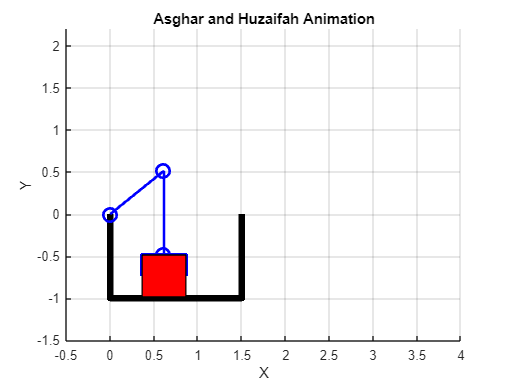

framesPerSecond = 9;
r = rateControl(framesPerSecond);
% Uncomment if you want to create a video
v = VideoWriter("bombDisposal.mp4");
open(v);
for i = 1:size(qs,1)
    q = qs(i,:);
    
    % Update the arm
    P = [q(2)*cosd(q(1)), q(2)*sind(q(1))];
    l1.XData = [0, P(1)];
    l1.YData = [0, P(2)];
    Q = [P(1)+cosd(q(1)+q(3)), P(2)+sind(q(1)+q(3))];
    l2.XData = [P(1), Q(1)];
    l2.YData = [P(2), Q(2)];
    
    % Update the end-effector and bomb
    phi = q(1)+q(3);
    p1 = [[0.25, .25, -.25, -.25 ]; [-.25, 0, 0, -.25]];
    R = eul2rotm([deg2rad(phi+90) 0 0]);
    p1 = R(1:2,1:2)*p1+[Q(1); Q(2)];
    l.XData = p1(1,:);
    l.YData = p1(2,:);
    p2 = [[-.25 .25 .25 -.25];[0 0 -.5 -.5]];
    p2 = R(1:2,1:2)*p2+[Q(1); Q(2)];
    b.XData = p2(1,:);
    b.YData = p2(2,:);
    
    % Uncomment if you want to create a video
    frame = getframe(gcf);
    writeVideo(v,frame);
    waitfor(r);
end

close(v)


**Play the file **

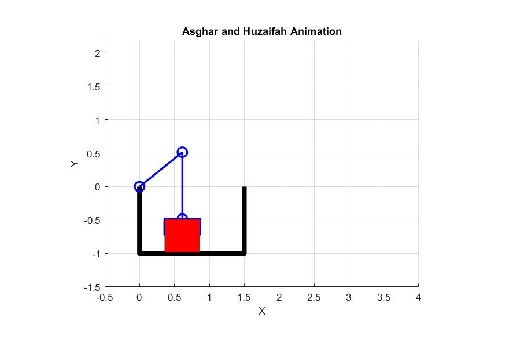

% Load the .avi file
videoObj = VideoReader('bombDisposal.mp4.avi');

% Create a figure to display the video
figure;

% Read and display each frame of the video
while hasFrame(videoObj)
    frame = readFrame(videoObj);
    imshow(frame);
    drawnow;
end